Image1a = imread("Image1a.tif");
Image1b = imread("Image1b.tif");

% imshow(Image1a)
% imshow(Image1b)

% [H, teta,ro] = hough(Image1a,'Rhoresolution',5,'Theta', -90:0.5:89.5);
% imshow(H)
% 
% [Hb, teta,ro] = hough(Image1b,'Rhoresolution',5,'Theta', -90:0.5:89.5);
% imshow(H)

%contrast stretching
% a = min(H(:));
% b = max(H(:));
% H1 = (H-a)/(b-a);
% imshow(H1)

% [r,t] = find(H==max(H(:)));
% [r2,t2] = find(Hb==max(Hb(:)));

% angle = teta(t);
% vinkel = angle(1,1);
% angle_fix = 90-vinkel;

% angle2 = teta(t2)
% vinkel2 = angle2(1,1)
% angle_fix2 = 90+vinkel2

% Image1a_rotated = imrotate(Image1a, -angle_fix,'bicubic','crop');
% imshow(Image1a_rotated)

% Image1b_rotated = imrotate(Image1b, angle_fix2,'bicubic','crop');
% imshow(Image1b_rotated)

# 2) Morphology

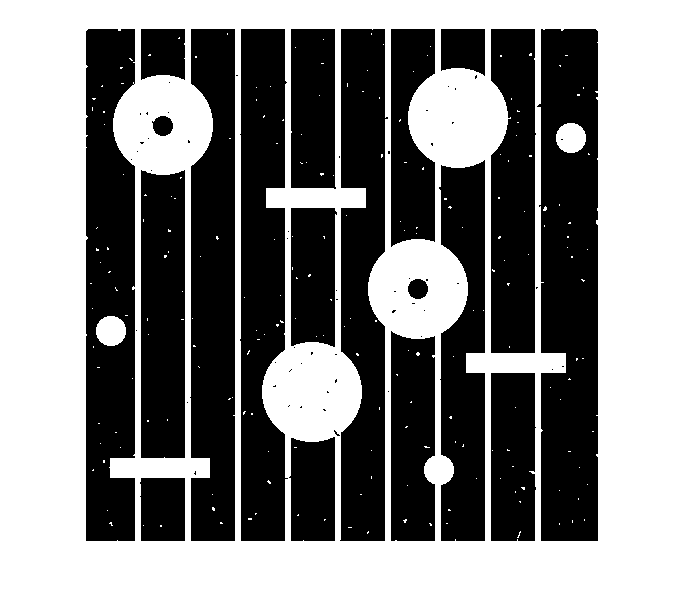

Image1c = imread("Image1c.tif");
imshow(Image1c)


r_small = 14;
r_big = 50;

SE = strel('disk',3);
% disp(SE.Neighborhood);

% noise removed
IM2 = imopen(Image1c,SE);
IM3 = imclose(IM2,SE);
% imshow(IM3)


% lines romved
SE1 = strel('line',10,0);

IM4 = imopen(IM3,SE1);
Image1c_clean = imclose(IM4,SE1);
% imshow(Image1c_clean)

%rectangles removed
SE2 = strel('disk',11);

IM5 = imopen(Image1c_clean,SE2);
Image1c_disk = imclose(IM5,SE2);
% imshow(Image1c_disk)

% All disk removed
SE3 = strel('rectangle', [15,100]);

IM6 = imopen(Image1c_clean,SE3);
Image1c_rect = imclose(IM6,SE3);
% imshow(Image1c_rect)

% Small disk removed
SE4 = strel('rectangle', [25,17]);

IM7 = imopen(Image1c_clean,SE4);
Image1c_bigDisk = imclose(IM7,SE4);
% imshow(Image1c_bigDisk)

% RGB-image
[r,c] = size(Image1c);
RGB = zeros(r,c,3);

RGB(:,:,1) = Image1c_disk-Image1c_bigDisk;
RGB(:,:,2) = Image1c_bigDisk;
RGB(:,:,3) = Image1c_rect;
% imshow(RGB)

rice = imread("rice-shaded.tif");
% imshow(rice)

SE5 = strel("disk",15);
IM8 = imopen(rice,SE5);
segment = rice- IM8;
binary = im2bw(segment,0.1);
% imshow(binary)

# 3) Labelling and object features

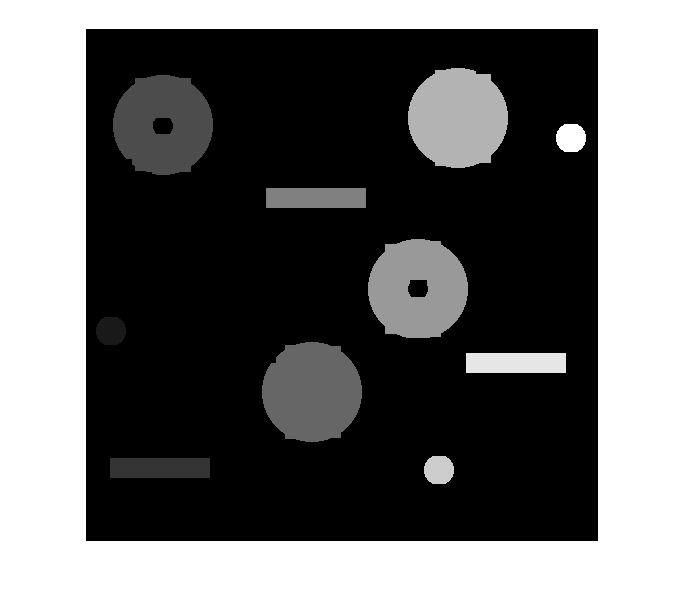

L = bwlabel(Image1c_clean);
imshow(L,[])

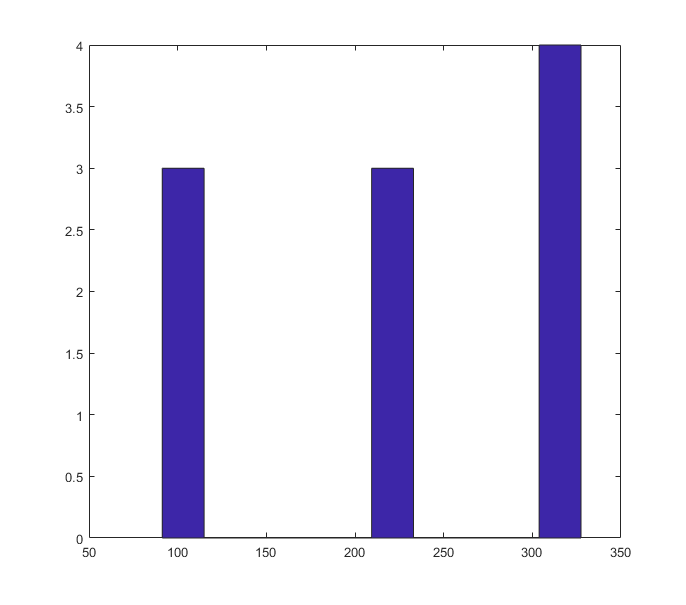


S = regionprops(L, "Area", "Perimeter","EulerNumber");

for n=1:length(S)
    Perimeter(n) = S(n).Perimeter;
    Area(n) = S(n).Area;
    Euler(n) = S(n).EulerNumber;
end

LargeO = find(Area>3000);
LargeO_Im = zeros(r,c); % creates an empty matrix

for n=1:length(LargeO) % the number of large objects
    LargeO_Im(L==LargeO(n))=1; % Large object area is set to 1
end

% Perimeter(LargeO)
BW = bwareafilt(logical(mat2gray(L)),[3000 10000]);
% imshow(BW)

hist(Perimeter);

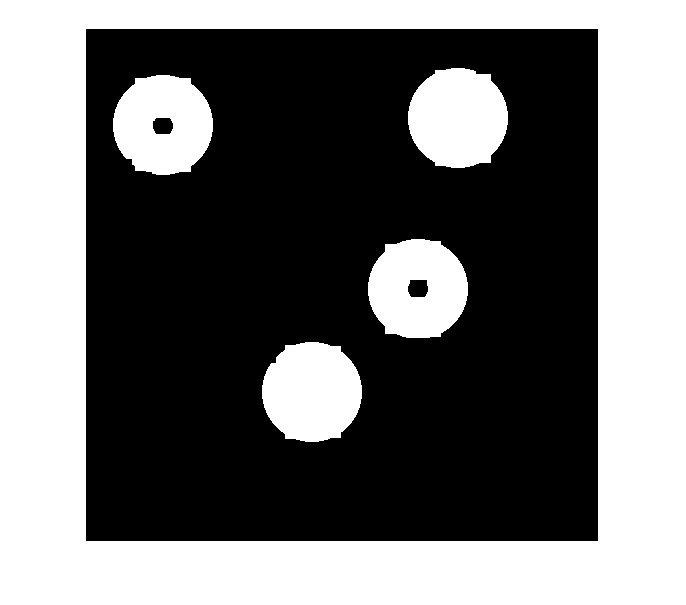

small_per = find(Perimeter < 130);
big_per = find(Perimeter>300 & (Euler == 1));
big_per2 = find(Perimeter>300);

big_per_Im = zeros(r,c); % creates an empty matrix

for n=1:length(big_per) % the number of large objects
    big_per_Im(L==big_per(n))=1; % Large object area is set to 1
end

BW2 = bwareafilt(logical(mat2gray(L)),[3000 10000]);
imshow(BW2)